# Solving Quadratic Programming Problem

Problem description :

To find values of x that :   $min\text{ }f\left(x\right)=\text{ }\frac{1}{2}x_1^2 +\text{ }x_2^2 −\text{ }x_1 x_2 −2x_1 −6x_2$

subject to $\left\lbrace \begin{array}{c}
x_1 +\text{ }x_2 \text{ }\le 2\\
−x_1 +2x_2 \text{ }\le 2\\
2x_1 +\text{ }x_2 \text{ }\le 3\\
0\text{ }\le \text{ }x_1 \\
0\text{ }\le \text{ }x_2 
\end{array}\right.$

In matrices notation, the form can be expressed as  :   $min\text{ }f\left(\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack \right)=\text{ }\frac{1}{2}{\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack }^T \bullet \text{ }\left\lbrack \begin{array}{c}
1 & −1\\
−1 & 2
\end{array}\right\rbrack \bullet \text{ }\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack +\text{ }{\left\lbrack \begin{array}{c}
−2\\
−6
\end{array}\right\rbrack }^T \bullet \text{ }\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$

s.t. $\left\lbrace \begin{array}{c}
\left\lbrack \begin{array}{c}
1 & −1\\
−1 & 2\\
2 & 1
\end{array}\right\rbrack \bullet \text{ }\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack \text{ }\le \text{ }\left\lbrack \begin{array}{c}
2\\
2\\
3
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack \text{ }\le \text{ }\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack 
\end{array}\right.$

where : $Χ=\text{ }\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack ,\text{         }\text{ }Η=\text{ }\left\lbrack \begin{array}{c}
1 & −1\\
−1 & 2
\end{array}\right\rbrack ,\text{   }f=\text{ }\left\lbrack \begin{array}{c}
−2\\
−6
\end{array}\right\rbrack ,\text{  }A=\text{ }\left\lbrack \begin{array}{c}
1 & −1\\
−1 & 2\\
2 & 1
\end{array}\right\rbrack ,\text{  }b=\text{ }\left\lbrack \begin{array}{c}
2\\
2\\
3
\end{array}\right\rbrack ,\text{  }lb=\text{ }\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$

How to solve this quadratic programming problem?   When $\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack =\text{ }?,\text{ }then\text{ }we\text{ }can\text{ }find\text{ }the\text{ }minimal\text{ }f\left(\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack \right)value?\text{ }$

============================================================================================================================================================

Firstly, let us view his 3D surface diagram : 

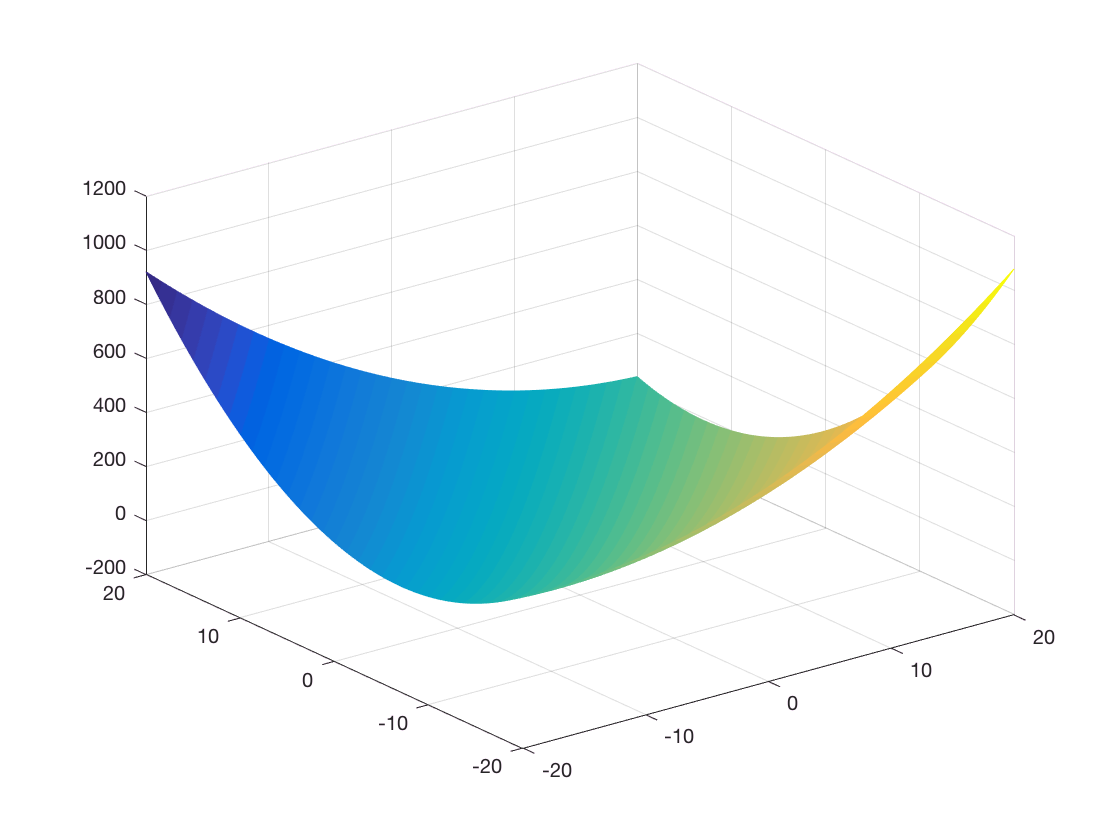

[x1, x2] = meshgrid(-20:0.05:20);
z = 0.5 * (x1).^2 + (x2).^2 - x1.*x2 - 2 * x1 - 6 * x2;
color = gradient(z);
mesh(x1, x2, z, color)

% Enter all the coefficient matrices :
H = [ 1, -1;
     -1, 2];
 
f = [-2;
     -6];
 
A = [ 1, 1;
     -1, 2;
      2, 1];
  
b = [2;
     2;
     3];
 
lb = [0;
      0];

Step 1 :  Set the options to use the "interior-point-convex" algorithm with no display

options = optimoptions('quadprog', 'Algorithm', 'interior-point-convex', 'Display', 'off');

Error using optimoptions (line 118)
Invalid value for OPTIONS parameter Display:
 must be 'off', 'none', 'final', 'final-detailed', 'iter', or 'iter-detailed'.

Step 2 : Call quadprog

[x, fval, exitflag, output, lambda] = quadprog(H, f, A, b, [], [], lb, [], [], options)

An exit flag of 1 means that the result is local minimum.

Because H is a positive definite matrix, this problem is convex. So the minimum is a global minimum. 

The eigenvalues of matrix H are positive :

H_eigen_value = eig(H)